# Berechnung von Mittelwert, Varianz und Autokorrelation einer Cosinusschwingung mit gleichverteilter Phase

Gegenben ist der Zufallsprozess einer Cosinusschwingung mit gleichverteilter Phase


$$X(\eta, t) = A_0\cdot\cos(\omega t + \phi(\eta)) \qquad \text{mit}\qquad f_\phi(\phi) = \frac{1}{2\pi}$$


Von diesem Zufallsprozess  sollen nun

- Mittelwert $\mu_X(t)$

- Varianz $\sigma_X^2(t)$

- Autokorrelationsfunktion $\varphi_{XX}(t_1, t_2)$

berechnet werden.

#### Parameter

clear
N = 10000;
Nsamples = 500;

A0 = 3;
f = 50;

w = 2*pi*f;
tmax = 100e-3;
t = linspace(0, tmax, Nsamples);

#### Zufallsvariable der Phase $\phi_0$

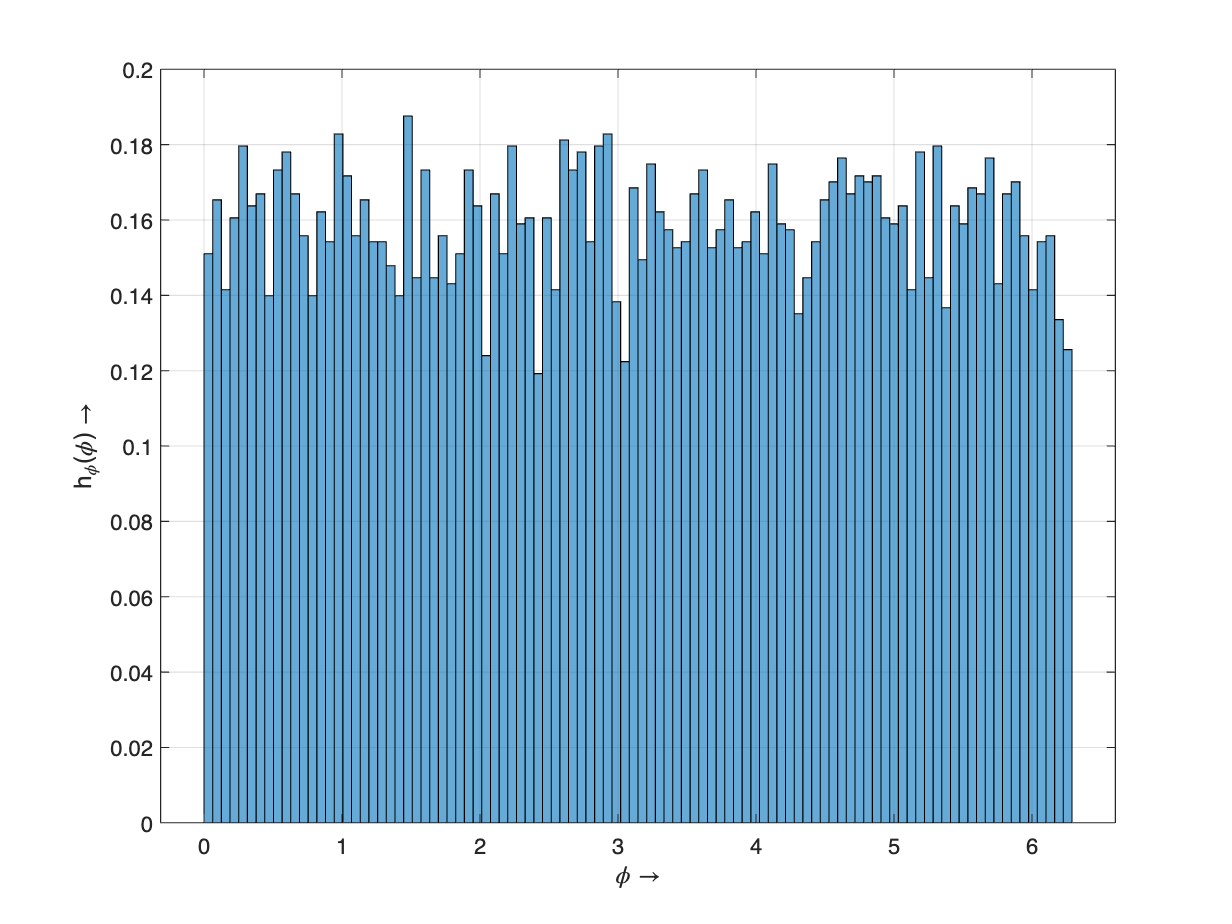

phi = 2*pi*rand(1, N);

histogram(phi, N/100, 'Normalization', 'pdf'), xlabel('\phi\rightarrow'), ylabel('h_\phi(\phi)\rightarrow'), grid on

#### Aufstellen des Zufallsprozesses

phi_t = repmat(w*t, N, 1) + phi.';
X = A0*cos(phi_t);

#### Berechnung des Mittelwertes

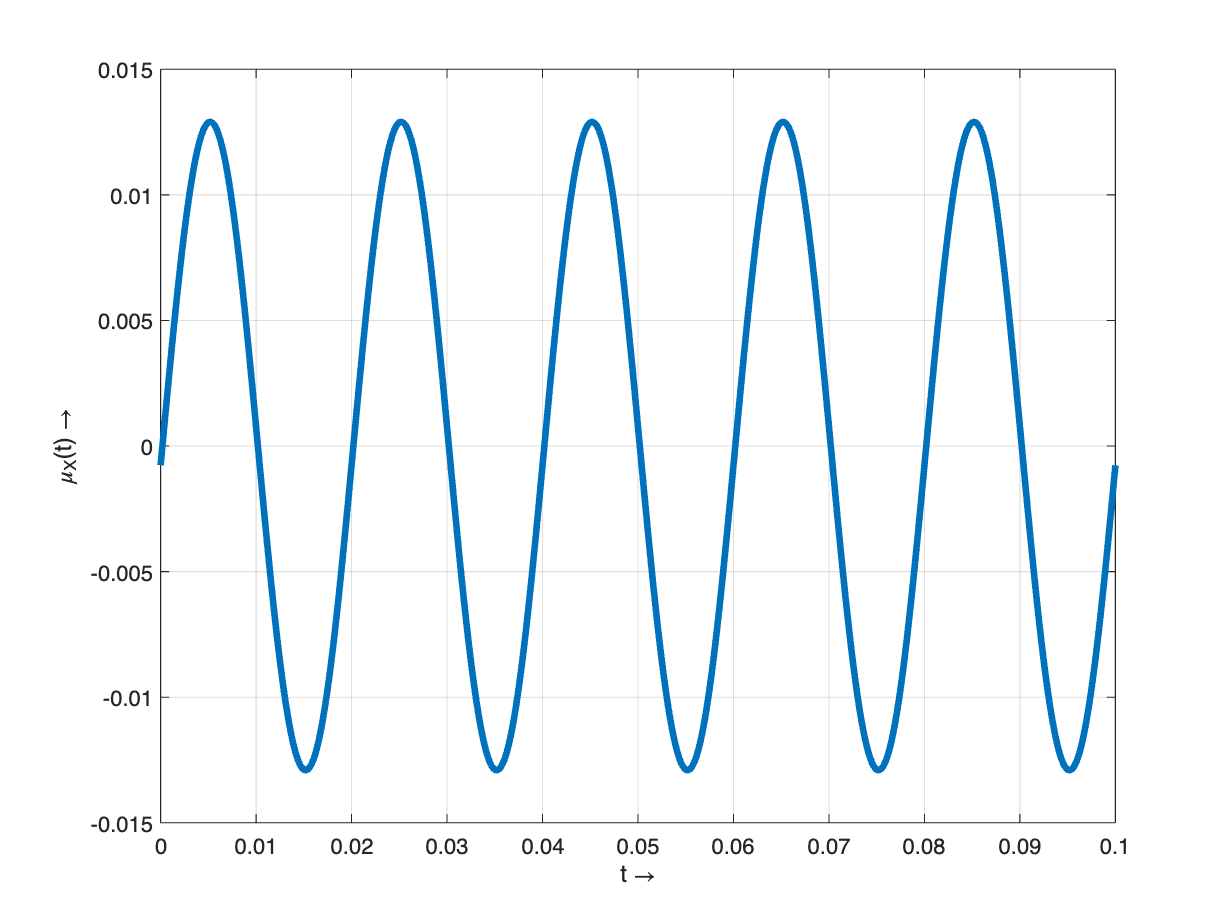

muX = mean(X);
plot(t, muX, LineWidth=3), xlabel('t\rightarrow'), ylabel('\mu_X(t)\rightarrow'), grid on

mean(muX)

ans = -1.5332e-06

#### Berechnung der Varianz

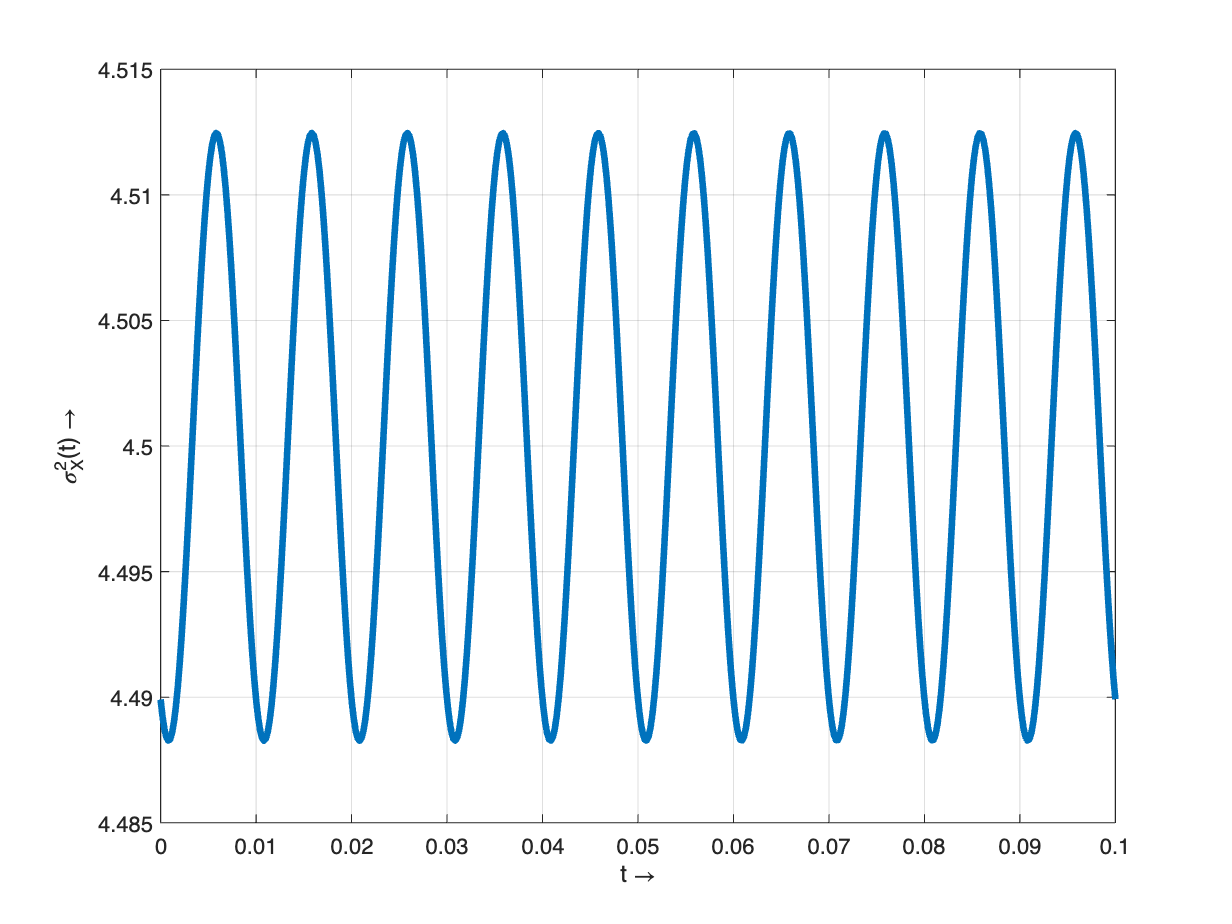

sXs = var(X);
plot(t, sXs, LineWidth=3), xlabel('t\rightarrow'), ylabel('\sigma_X^2(t)\rightarrow'), grid on

mean(sXs)

ans = 4.5003

#### Berechnen der Autokorrelationsfunktion

phi_XX = zeros(length(t));

for i1 = 1:size(phi_XX, 1)
    for i2 = 1:size(phi_XX, 2)
        phi_XX(i1, i2) = mean(X(:,i1).*X(:,i2));
    end
end

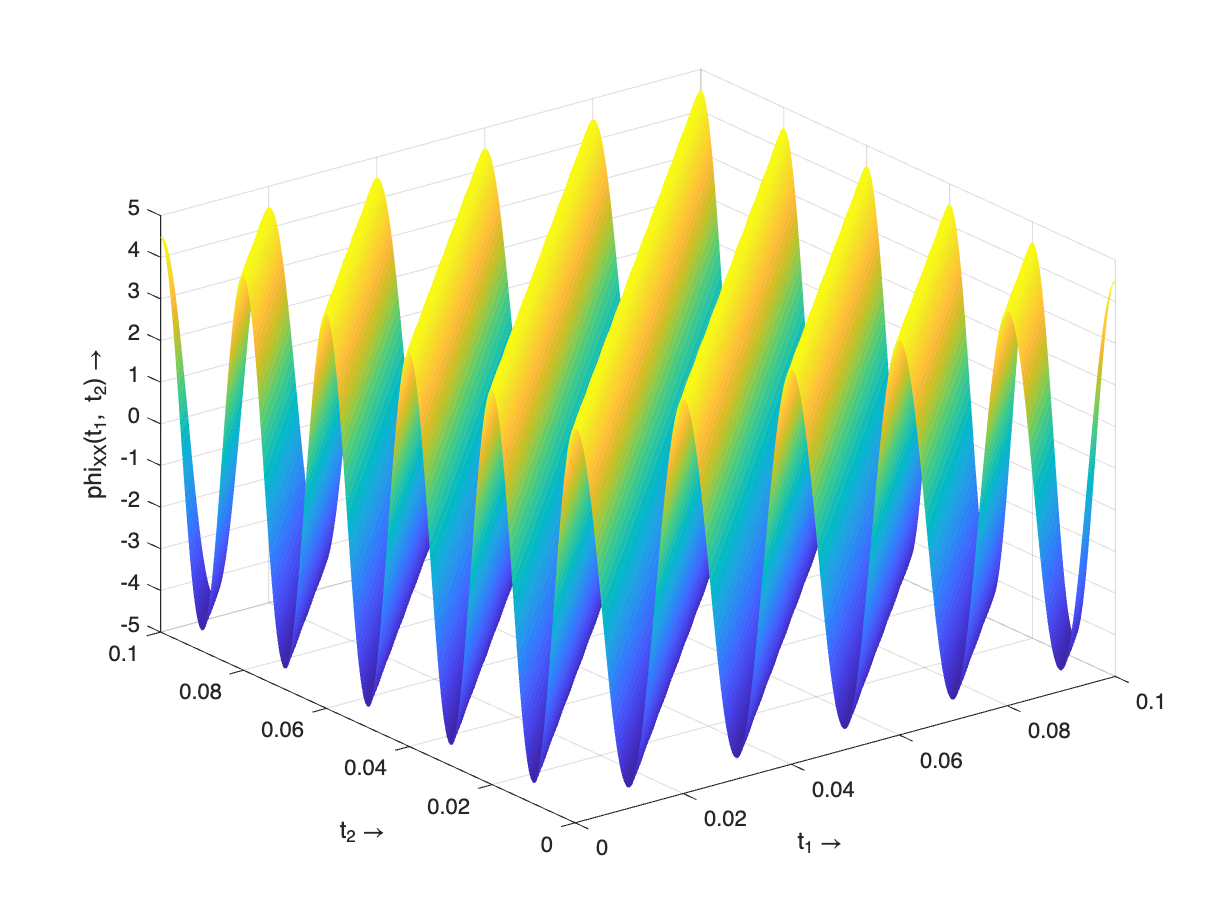

mesh(t, t, phi_XX), xlabel('t_1\rightarrow'), ylabel('t_2\rightarrow'), zlabel('phi_{XX}(t_1, t_2)\rightarrow'), grid on

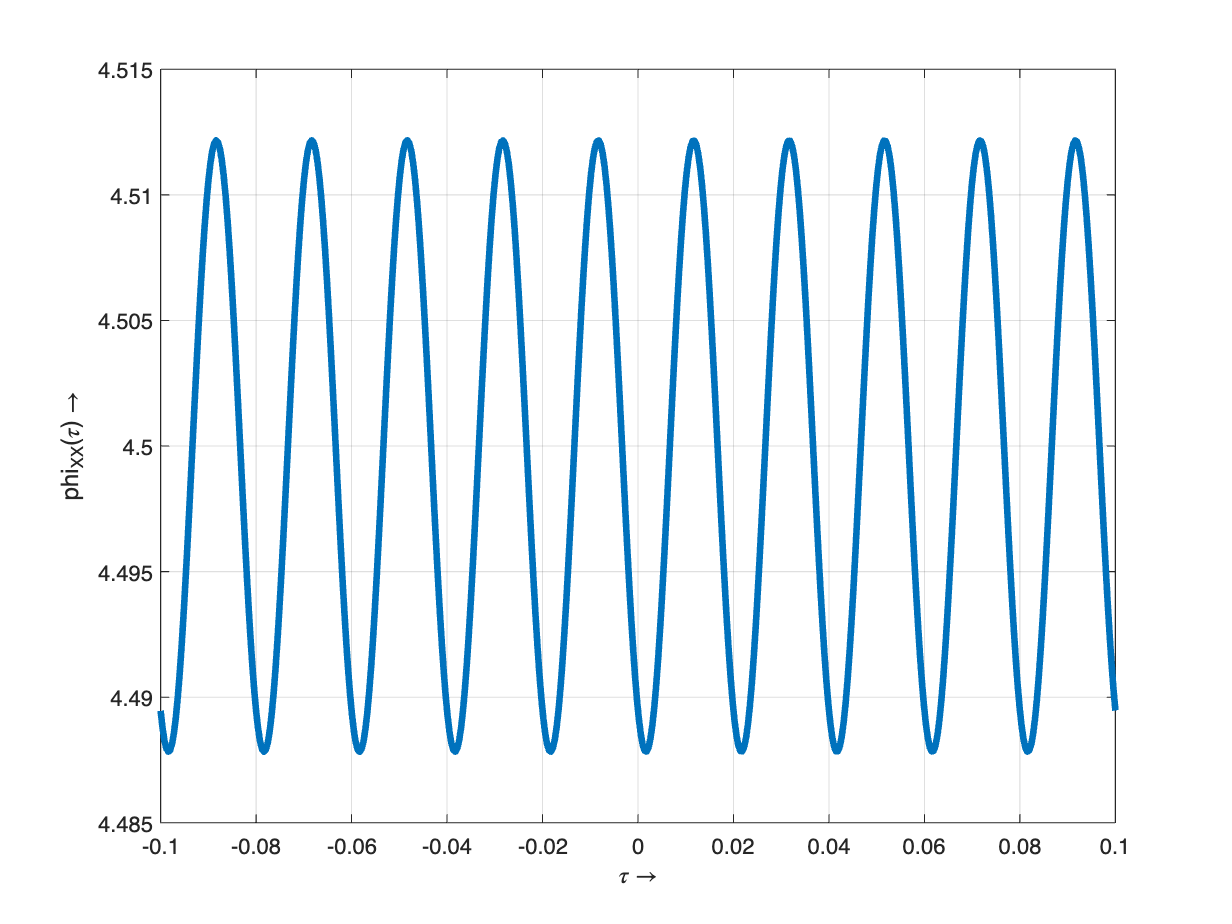

tau = t-fliplr(t);
plot(tau, diag(phi_XX), LineWidth=3), xlabel('\tau\rightarrow'), ylabel('phi_{XX}(\tau)\rightarrow'), grid on

#### Alternative Berechnung der Autokorrelationsfunktion

phi_XX_2 = zeros(N,Nsamples);

for k = 1:N
    for i = 1:Nsamples
        phi_XX_2(k,i) = 1/Nsamples*sum(X(k,i:end).*X(k,1:end-i+1));
    end
end
phi_XX_2 = mean(phi_XX_2);

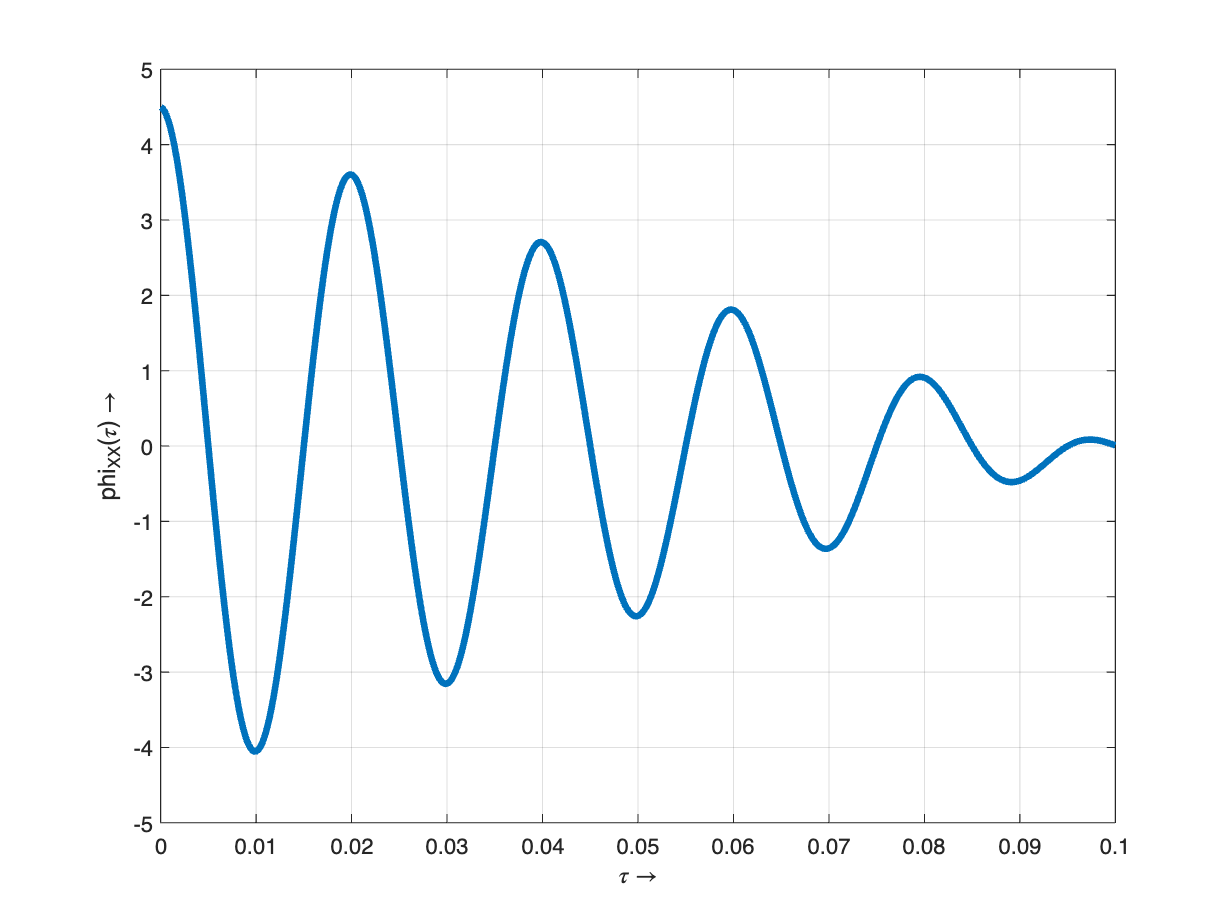

tau = linspace(0, tmax, Nsamples);
plot(tau, phi_XX_2, LineWidth=3), xlabel('\tau\rightarrow'), ylabel('phi_{XX}(\tau)\rightarrow'), grid on

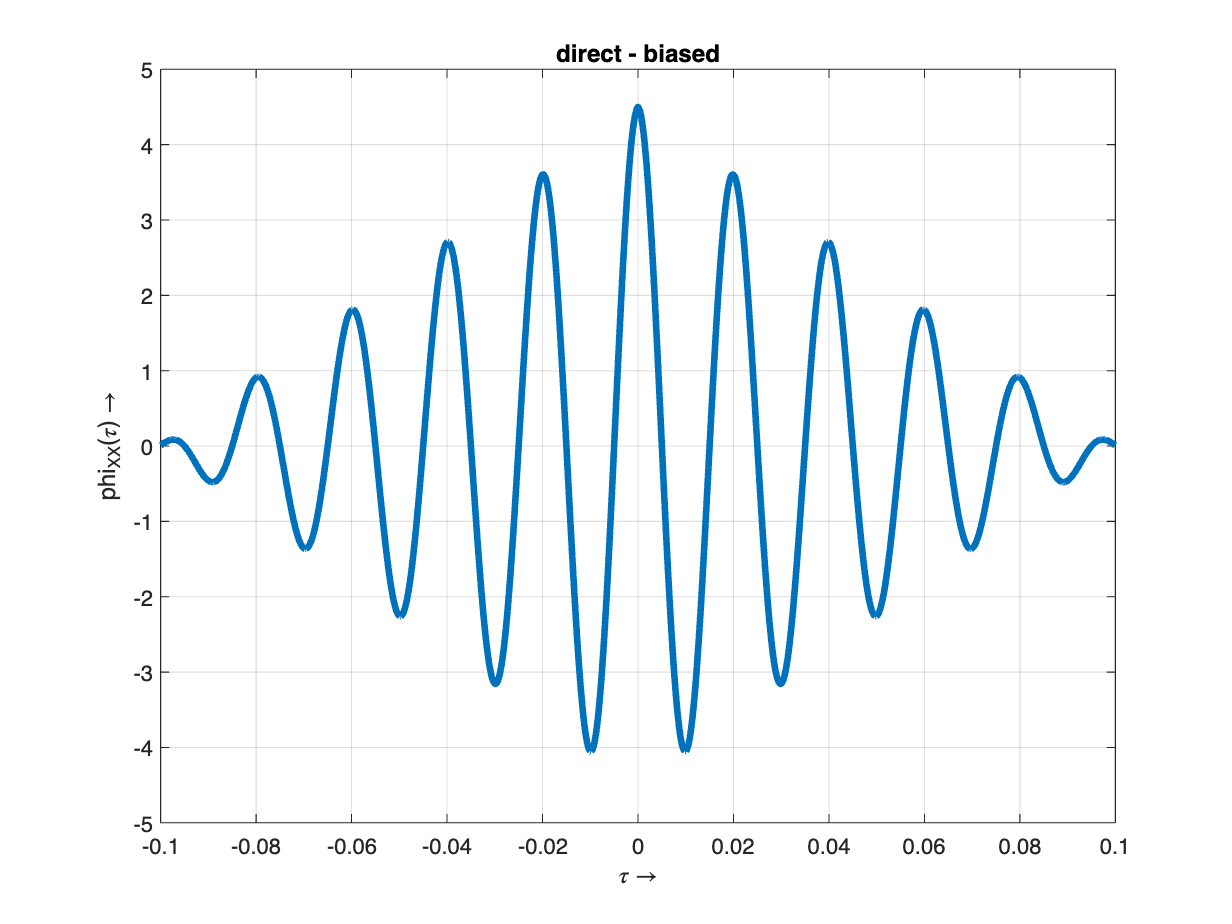

phi_XX_2_both = [phi_XX_2(end:-1:2), phi_XX_2];
tau_both = [-tau(end:-1:2), tau];
plot(tau_both, phi_XX_2_both, LineWidth=3), xlabel('\tau\rightarrow'), ylabel('phi_{XX}(\tau)\rightarrow'), grid on, title('direct - biased')

#### Berechnung der Autocorrelationsfunktion mittels xcorr()

phi_XX_3 = zeros(N,2*Nsamples-1);

for k = 1:N
    [phi_XX_3(k,:), lags] = xcorr(X(k,:), X(k,:), 'biased');
end
phi_XX_3 = mean(phi_XX_3);

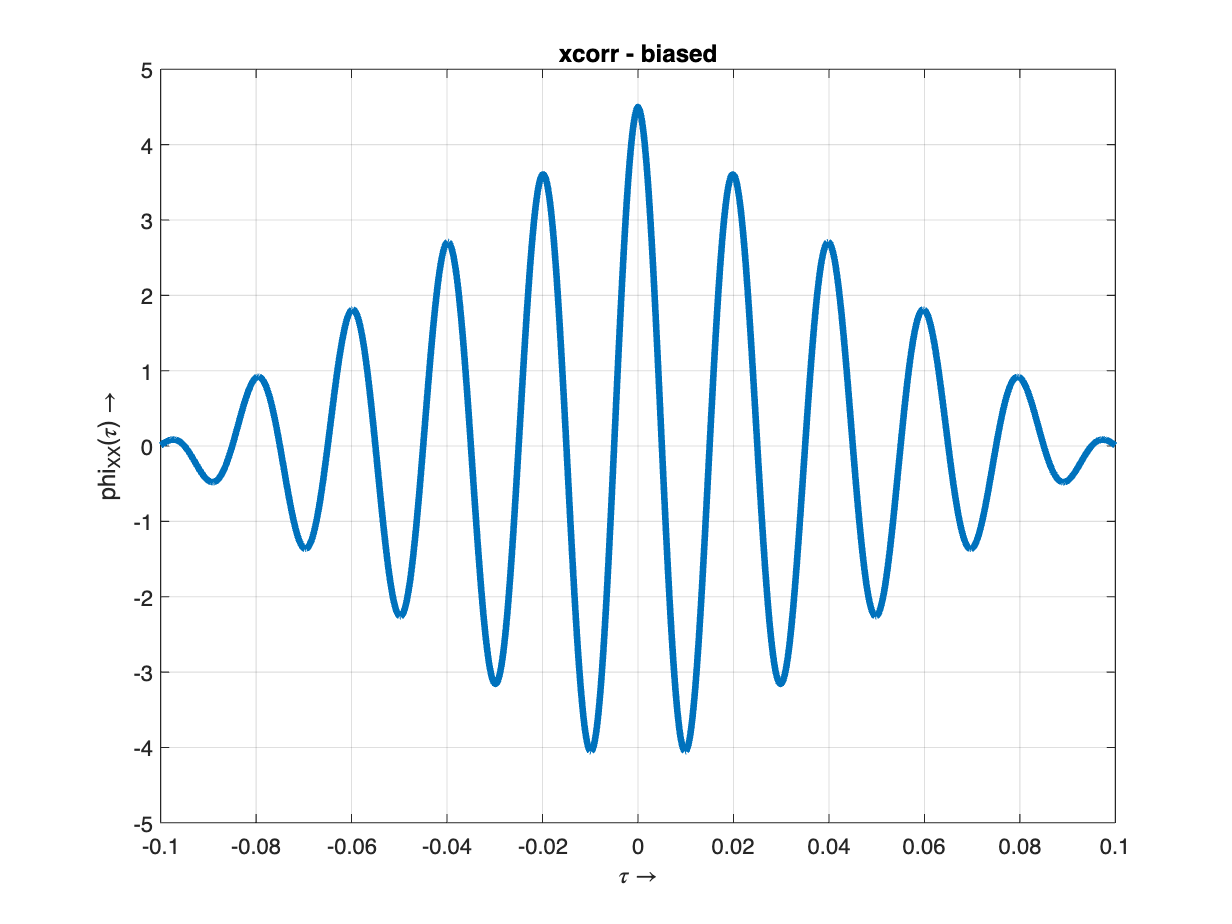

Ts = t(2)-t(1);
plot(lags*Ts, phi_XX_3, LineWidth=3), xlabel('\tau\rightarrow'), ylabel('phi_{XX}(\tau)\rightarrow'), grid on, title('xcorr - biased')

phi_XX_4 = zeros(N,2*Nsamples-1);

for k = 1:N
    [phi_XX_4(k,:), lags] = xcorr(X(k,:), X(k,:), 'unbiased');
end
phi_XX_4 = mean(phi_XX_4);

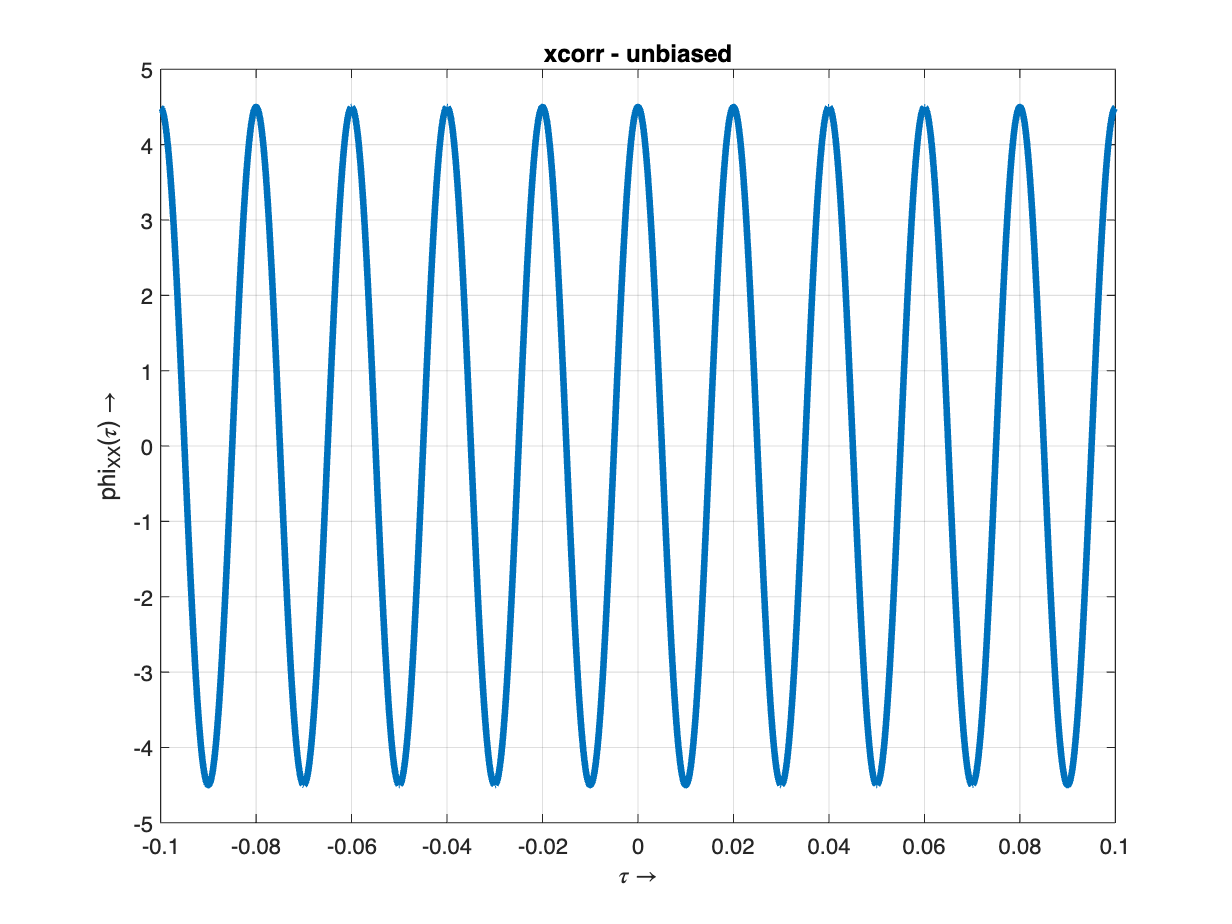

plot(lags*Ts, phi_XX_4, LineWidth=3), xlabel('\tau\rightarrow'), ylabel('phi_{XX}(\tau)\rightarrow'), grid on, title('xcorr - unbiased')

phi_XX_5 = zeros(N, Nsamples);

for k = 1:N
    for i = 1:Nsamples
        phi_XX_5(k,i) = mean(X(k,i:end).*X(k,1:end-i+1));
    end
end
phi_XX_5 = mean(phi_XX_5);
phi_XX_5 = [phi_XX_5(end:-1:2), phi_XX_5];

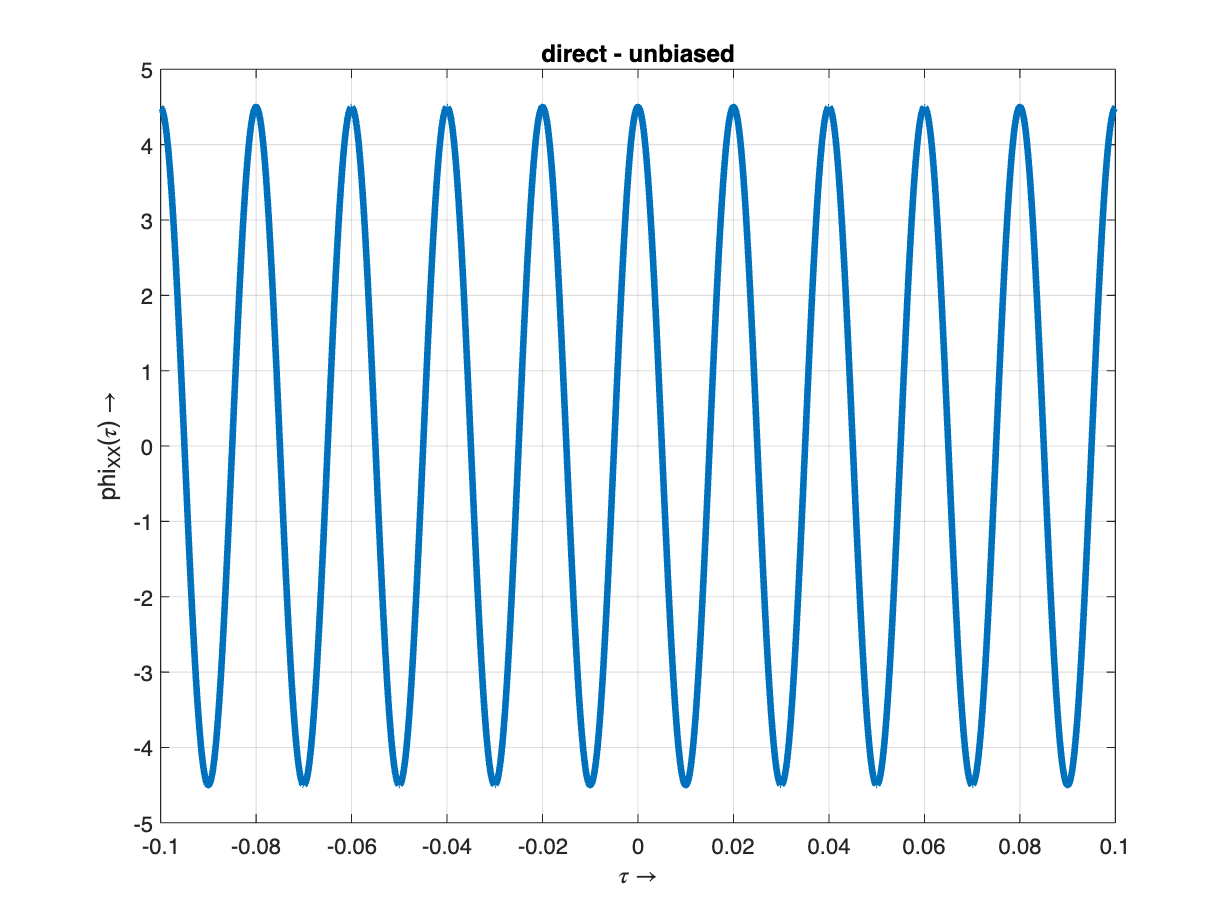

plot(tau_both, phi_XX_5, LineWidth=3), xlabel('\tau\rightarrow'), ylabel('phi_{XX}(\tau)\rightarrow'), grid on, title('direct - unbiased')